# SVM using Sequential Minimal Optimization (Simplified SMO)

## Initialization (Dataset: LinearlySeprerableData.csv)

clear all;clc;
data=csvread('LinearlySeprerableData.csv');

- Zscore Normalization

data(:,1:end-1)=zscore(data(:,1:end-1));

- Inputs  & Target of inputs

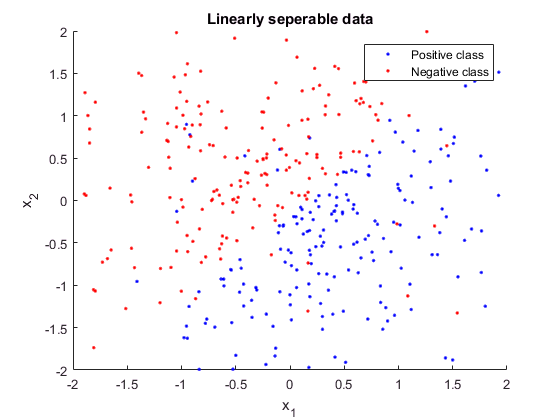

x = data(:,1:end-1);
y = data(:,end);
figure
hold on
scatter(x(y==1,1),x(y==1,2),'.b')
scatter(x(y==-1,1),x(y==-1,2),'.r')
axis ([-2 2 -2 2])
title('Linearly seperable data')
xlabel('{x_1}'),ylabel('{x_2}')
legend('Positive class','Negative class')
hold off

- Total number of data points

N = length(data);

- Regularization parameter, C (optimal) using Cross-Validation techniques

C = 0.5;

- Tolerence

tol = 10e-5;

- Lagrange Multipliers

alpha = zeros(N,1);

- Initialize Bias

bias = 0;

##  Sequential Minimal Optimization (SMO) Algorithm

while (1)
    
    changed_alphas=0;
    N=size(y,1);
    fprintf('Possible support vectors: %d',N)
    
    for i=1:N
        Ei=sum(alpha.*y.*K(x,x(i,:),'l'))-y(i);
        
        if ((Ei*y(i) < -tol) && alpha(i) < C) || (Ei*y(i) > tol && (alpha(i) > 0))
            
            for j=[1:i-1,i+1:N]
                Ej=sum(alpha.*y.*K(x,x(j,:),'l'))-y(j);
                  alpha_iold=alpha(i);
                  alpha_jold=alpha(j);

                  if y(i)~=y(j)
                      L=max(0,alpha(j)-alpha(i));
                      H=min(C,C+alpha(j)-alpha(i));
                  else 
                      L=max(0,alpha(i)+alpha(j)-C);
                      H=min(C,alpha(i)+alpha(j));
                  end

                  if (L==H)
                      continue
                  end
                  
                  eta = 2*K(x(j,:),x(i,:),'l')-K(x(i,:),x(i,:),'l')-K(x(j,:),x(j,:),'l');
                  
                  if eta>=0
                      continue
                  end
                  
                  alpha(j)=alpha(j)-( y(j)*(Ei-Ej) )/eta;
                  
                  if alpha(j) > H
                      alpha(j) = H;
                  elseif alpha(j) < L
                      alpha(j) = L;
                  end

                  if norm(alpha(j)-alpha_jold) < tol
                      continue
                  end
                  
                  alpha(i)=alpha(i) + y(i)*y(j)*(alpha_jold-alpha(j));
                  
                  b1 = bias - Ei - y(i)*(alpha(i)-alpha_iold)*K(x(i,:),x(i,:),'l')...
                      -y(j)*(alpha(j)-alpha_jold)*K(x(i,:),x(j,:),'l');
                  
                  b2 = bias - Ej - y(i)*(alpha(i)-alpha_iold)*K(x(i,:),x(j,:),'l')...
                      -y(j)*(alpha(j)-alpha_jold)*K(x(j,:),x(j,:),'l');
           
                  if 0<alpha(i)<C
                      bias=b1;
                  elseif 0<alpha(j)<C
                      bias=b2;
                  else
                      bias=(b1+b2)/2;
                  end
                  
                  changed_alphas=changed_alphas+1;
            end
        end
    end
    
    if changed_alphas==0
        break
    end
    
    x=x((find(alpha~=0)),:);
    y=y((find(alpha~=0)),:);
    alpha=alpha((find(alpha~=0)),:);
end

Possible support vectors: 400

Possible support vectors: 155

Possible support vectors: 152

Possible support vectors: 151

Possible support vectors: 150

Possible support vectors: 149

Possible support vectors: 148

Possible support vectors: 148

Possible support vectors: 148

Possible support vectors: 148

Possible support vectors: 148

## Weights

W=sum(alpha.*y.*x)

W =     1.7584   -1.6904


## Bias

bias =mean( y - x*W')

bias = -0.2096

## Support Vectors

fprintf('Number of support Vectors : %d',N)

Number of support Vectors : 148

Xsupport=x;Ysupport=y;

## Accuracy and F-measure

x=data(:,1:end-1);y=data(:,end);
fx=sign(W*x'+bias)';
[~, Accuracy, F_measure ] = confusionMatrix( y,fx )

Accuracy = 0.9375

F_measure = 0.9367

## Plotting the Decision Boundry

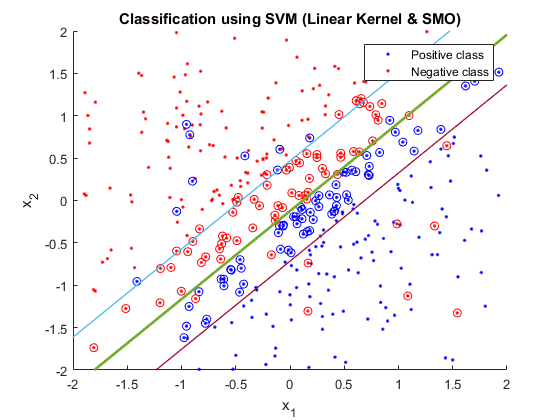

figure
hold on
scatter(x(y==1,1),x(y==1,2),'.b')
scatter(x(y==-1,1),x(y==-1,2),'.r')
scatter(Xsupport(Ysupport==1,1),Xsupport(Ysupport==1,2),'b')
scatter(Xsupport(Ysupport==-1,1),Xsupport(Ysupport==-1,2),'r')

syms x1 x2
fn=vpa((-bias-W(1)*x1)/W(2),6);
fn1=vpa((-1-bias-W(1)*x1)/W(2),6);
fn2=vpa((1-bias-W(1)*x1)/W(2),6);
fplot(fn,'Linewidth',2);
fplot(fn1,'Linewidth',1);
fplot(fn2,'Linewidth',1);
axis ([-2 2 -2 2])
title('Classification using SVM (Linear Kernel & SMO)')
xlabel('{x_1}'),ylabel('{x_2}')
legend('Positive class','Negative class')
hold off

% Reference: http://cs229.stanford.edu/materials/smo.pdf
% Bhartendu, Machine Learning & Computing